# Q3 Communication Systems

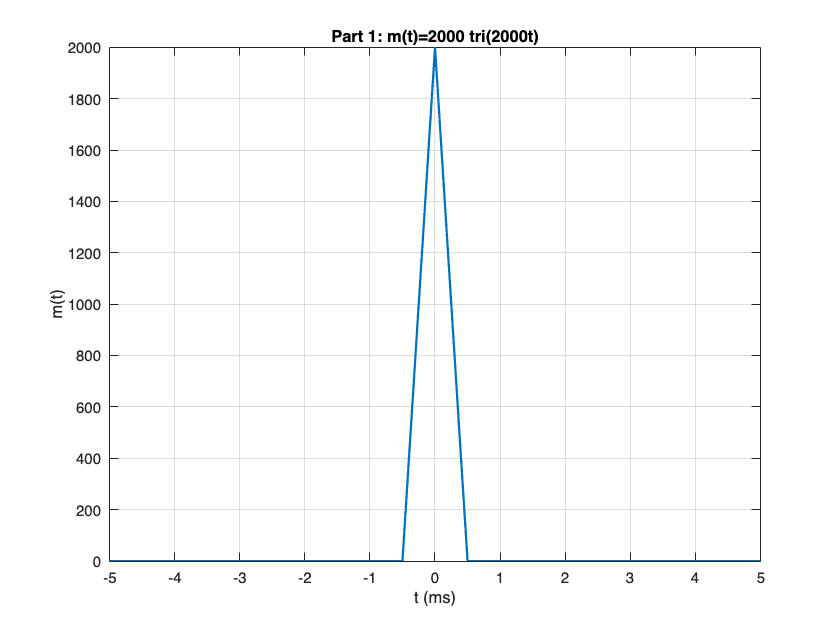

clear; close all; clc;

% Part 1 (Baseband processing)

% Baseband sampling (enough for message shape + filtfilt constraint)
Fs_bb = 100e3;                 % 100 kHz
Ts_bb = 1/Fs_bb;

% Time window long enough for filtfilt
tmin_bb = -5e-3;
tmax_bb =  5e-3;
t_bb = tmin_bb:Ts_bb:tmax_bb;

% 1) Generate m(t) = 2000*tri(2000t)
x_bb = 2000*t_bb;
tri_bb = zeros(size(x_bb));
idx_bb = abs(x_bb) < 1;
tri_bb(idx_bb) = 1 - abs(x_bb(idx_bb));
m_bb = 2000*tri_bb;

figure;
plot(t_bb*1e3, m_bb, 'LineWidth', 1.5); grid on;
xlabel('t (ms)'); ylabel('m(t)');
title('Part 1: m(t)=2000 tri(2000t)');

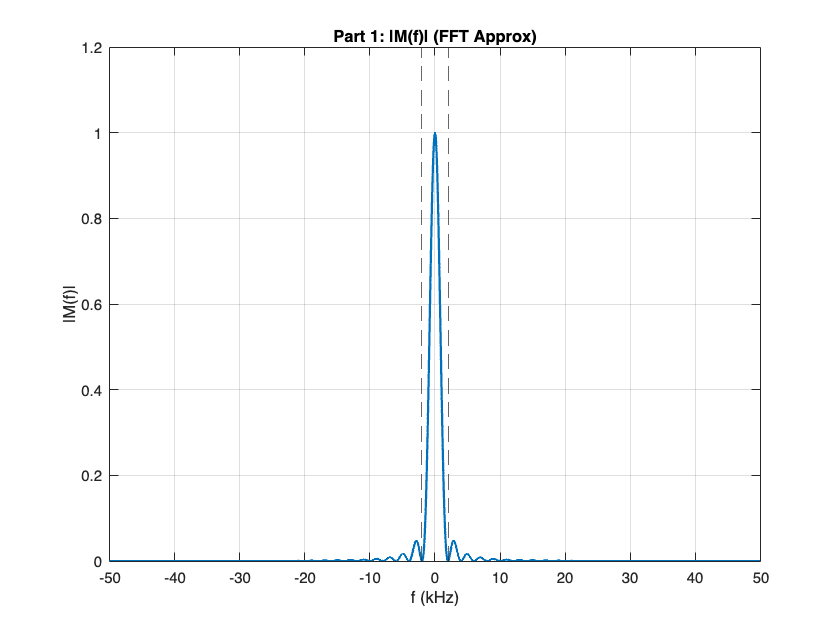

% 2) Spectrum using FFT (baseband)
N_bb = 2^nextpow2(length(m_bb)*8);
M_bb = fftshift(fft(m_bb, N_bb))*Ts_bb;
f_bb = (-N_bb/2:N_bb/2-1)*(Fs_bb/N_bb);

figure;
plot(f_bb/1e3, abs(M_bb), 'LineWidth', 1.5); grid on;
xlabel('f (kHz)'); ylabel('|M(f)|');
title('Part 1: |M(f)| (FFT Approx)');
xline(2,'--'); xline(-2,'--');


% 3) Effective bandwidth Beff (90% energy) in baseband
P_bb  = abs(M_bb).^2;
df_bb = Fs_bb/N_bb;

Etotal_bb = sum(P_bb)*df_bb;

mid_bb = N_bb/2 + 1;
Ppos_bb = P_bb(mid_bb:end);
Ecum_pos_bb = cumsum(Ppos_bb)*df_bb;

target_half_bb = 0.90*Etotal_bb/2;
k_bb = find(Ecum_pos_bb >= target_half_bb, 1, 'first');
Beff_bb = f_bb(mid_bb-1 + k_bb);

fprintf('Part 1: Estimated Beff (90%% energy) ≈ %.1f Hz\n', Beff_bb);

Part 1: Estimated Beff (90% energy) ≈ 830.1 Hz


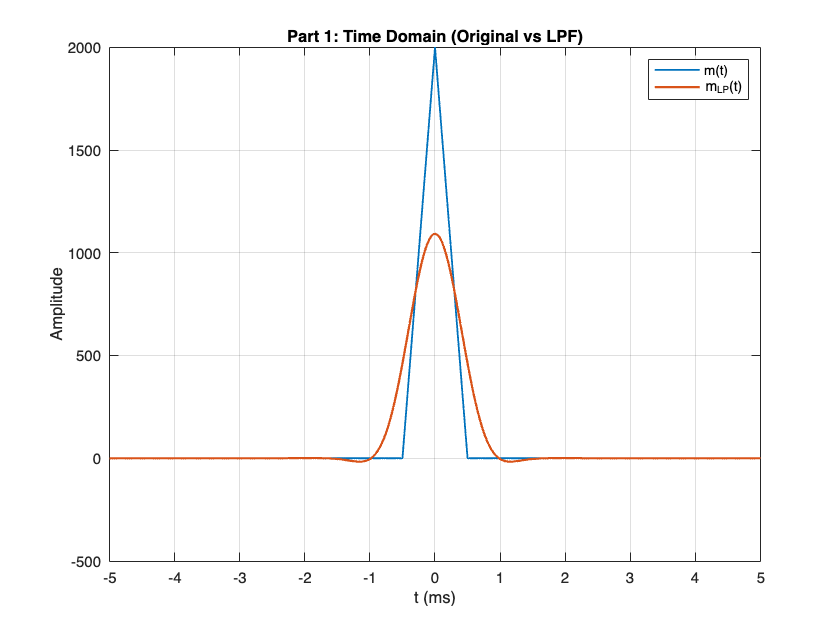


% 4) Lowpass filter with cutoff ~ Beff to get mLP(t)
Fc_bb = Beff_bb;
Wn_bb = Fc_bb/(Fs_bb/2);

Nfir_bb = 200;
Lx_bb = length(m_bb);

maxOrderAllowed_bb = floor(Lx_bb/3) - 2;
if Nfir_bb > maxOrderAllowed_bb
    warning('Part 1: Reducing FIR order from %d to %d for filtfilt.', Nfir_bb, maxOrderAllowed_bb);
    Nfir_bb = max(10, maxOrderAllowed_bb);
end

b_bb = fir1(Nfir_bb, Wn_bb, 'low', hamming(Nfir_bb+1));
mLP_bb = filtfilt(b_bb, 1, m_bb);

figure;
plot(t_bb*1e3, m_bb, 'LineWidth', 1.2); hold on;
plot(t_bb*1e3, mLP_bb, 'LineWidth', 1.5);
grid on; xlabel('t (ms)'); ylabel('Amplitude');
legend('m(t)','m_{LP}(t)');
title('Part 1: Time Domain (Original vs LPF)');

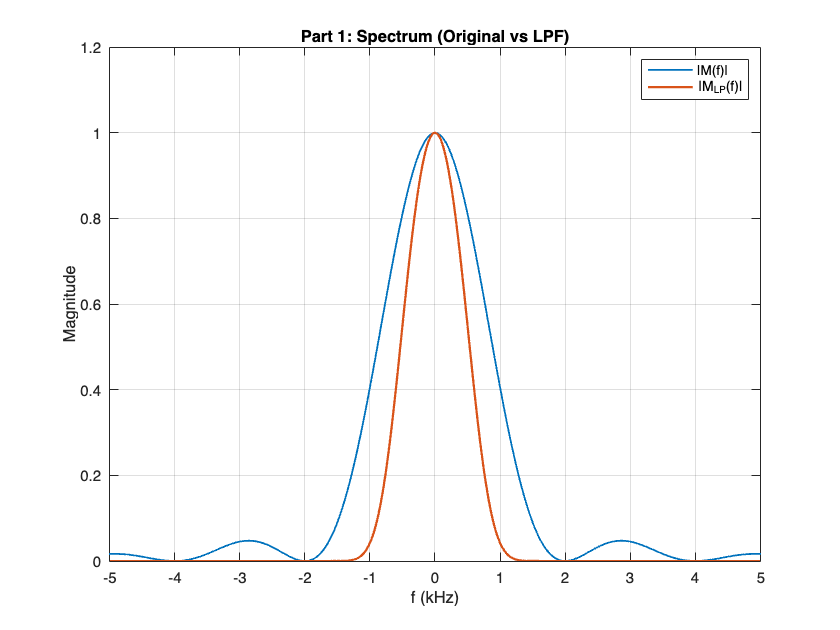


MLP_bb = fftshift(fft(mLP_bb, N_bb))*Ts_bb;

figure;
plot(f_bb/1e3, abs(M_bb), 'LineWidth', 1.2); hold on;
plot(f_bb/1e3, abs(MLP_bb), 'LineWidth', 1.5);
grid on; xlabel('f (kHz)'); ylabel('Magnitude');
legend('|M(f)|','|M_{LP}(f)|');
title('Part 1: Spectrum (Original vs LPF)');
xlim([-5 5]);

## Part 2 (FM modulation, RF sampling)

% RF sampling (must satisfy Fs_rf >= 2*fc)
Fs_rf = 100e6;                 % 100 MHz
Ts_rf = 1/Fs_rf;

fc = 10e6;                     % 10 MHz carrier

% Use a shorter time window for RF processing (computationally manageable)
tmin_rf = -1e-3;
tmax_rf =  1e-3;
t_rf = tmin_rf:Ts_rf:tmax_rf;

% Bring mLP from baseband grid to RF grid (no re-generation of message)
% Interpolate mLP_bb(t_bb) onto t_rf
mLP_rf = interp1(t_bb, mLP_bb, t_rf, 'linear', 0);   % outside range -> 0

% Choose fm_max and Delta_f (as in your Part 2 setup)
fm_max = 2e3;                   % based on first spectral zero around 2 kHz
Delta_f = 20e3;                 % 20 kHz (in [20,40] kHz), gives beta~10 if fm_max=2k
beta = Delta_f / fm_max;
fprintf('Part 2: Chosen Delta_f = %.0f Hz, beta = %.2f (fm_max=%.0f Hz)\n', Delta_f, beta, fm_max);

Part 2: Chosen Delta_f = 20000 Hz, beta = 10.00 (fm_max=2000 Hz)


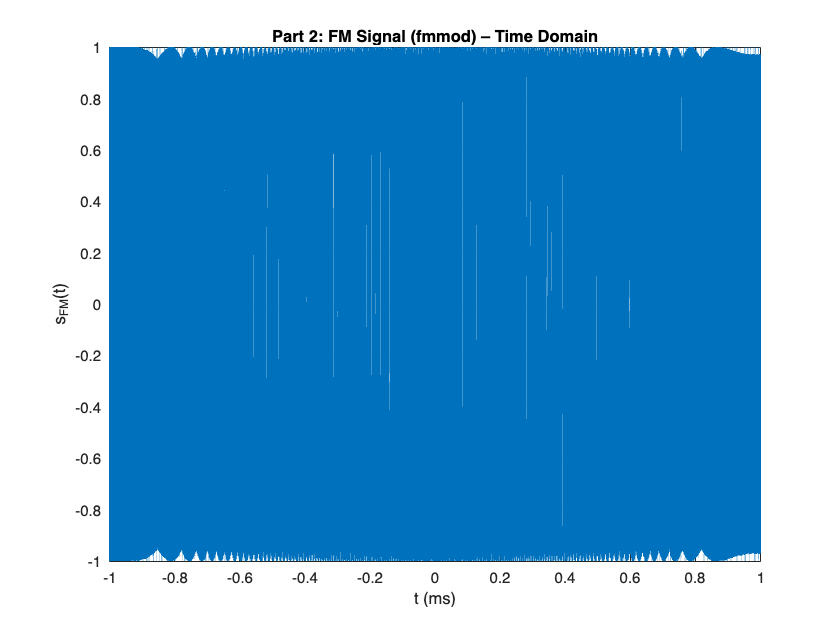

% Normalize message for fmmod convention
mLPn_rf = mLP_rf / (max(abs(mLP_rf)) + eps);

% FM modulation using fmmod (this is your desired signal)
sFM = fmmod(mLPn_rf, fc, Fs_rf, Delta_f);

% Time-domain plot (ONLY fmmod), not microsecond over-zoom
figure;
plot(t_rf*1e3, sFM, 'LineWidth', 1.0); grid on;
xlabel('t (ms)'); ylabel('s_{FM}(t)');
title('Part 2: FM Signal (fmmod) – Time Domain');

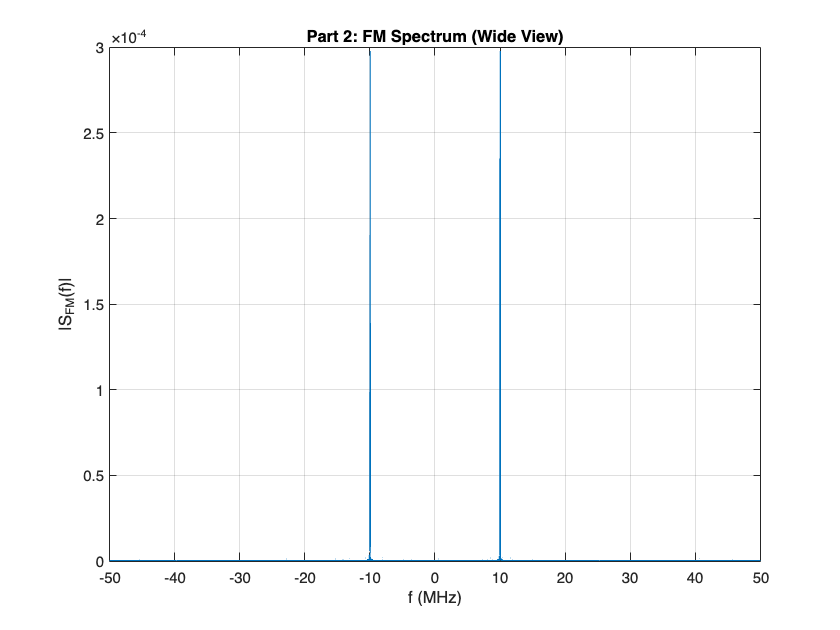

% Spectrum of FM signal (magnitude, linear), axis is f (not f-fc)
N_rf = 2^nextpow2(length(sFM));
S_rf = fftshift(fft(sFM, N_rf))*Ts_rf;
f_rf = (-N_rf/2:N_rf/2-1)*(Fs_rf/N_rf);

figure;
plot(f_rf/1e6, abs(S_rf), 'LineWidth', 1.2); grid on;
xlabel('f (MHz)'); ylabel('|S_{FM}(f)|');
title('Part 2: FM Spectrum (Wide View)');

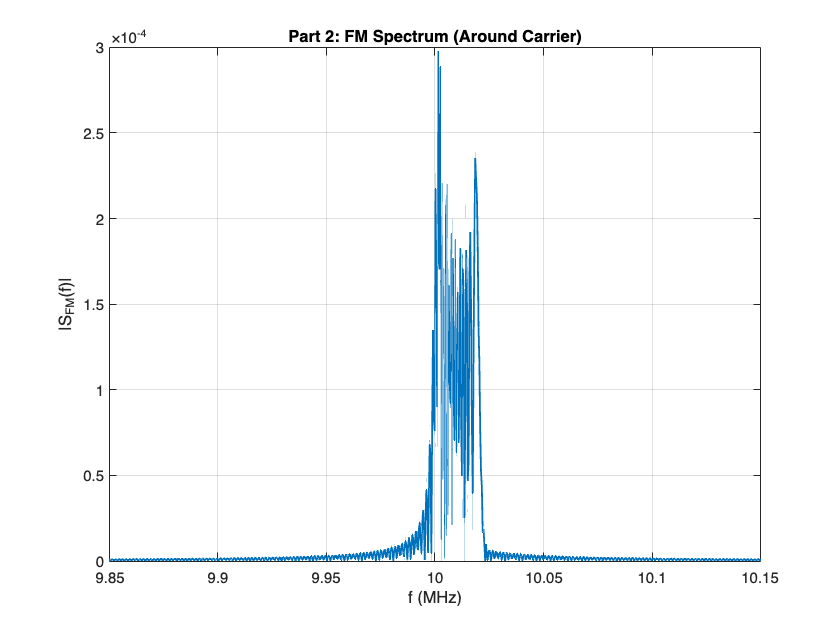

figure;
plot(f_rf/1e6, abs(S_rf), 'LineWidth', 1.2); grid on;
xlabel('f (MHz)'); ylabel('|S_{FM}(f)|');
title('Part 2: FM Spectrum (Around Carrier)');
xlim([(fc-150e3)/1e6 (fc+150e3)/1e6]);  % show fc ± 150 kHz

## Part 3 (FM demodulation)

%% 3.1) Narrowband FM at fbase = 500 kHz with mA(t)=400 tri(400t)
fbase = 500e3;

% Create Armstrong message on the SAME grid (time t_rf from Part 2)
xA = 400 * t_rf;                              % tri argument
triA = zeros(size(xA));
idxA = abs(xA) < 1;
triA(idxA) = 1 - abs(xA(idxA));
mA = 400 * triA;                               % m(t)=400 tri(400t)

% fm_max for this message (first spectral zero ~ 400 Hz)
fmA_max = 400;                               % Hz (for tri(400t))

% Choose small deviation to make FM narrowband (beta << 1)
fdevA1 = 40;                                 % Hz  => beta1 = 40/400 = 0.1 (narrowband)
betaA1 = fdevA1 / fmA_max;
fprintf('Part 3.1: beta (NBFM) = %.3f (should be <<1)\n', betaA1);

Part 3.1: beta (NBFM) = 0.100 (should be <<1)


% Normalize for fmmod convention
mAn = mA / (max(abs(mA)) + eps);

% Generate NBFM at 500 kHz
sNBFM = fmmod(mAn, fbase, Fs_rf, fdevA1);

% --- Comment for report (why narrowband is required) ---
% Armstrong starts from NBFM because the phase-modulation approximation and
% frequency-multiplier chain is intended to scale a small phase deviation.

% 3.2) Frequency multiplication
% Multiply frequency by Nmult using instantaneous phase:
% If s(t)=cos(theta(t)), then cos(N*theta(t)) multiplies carrier and deviation by N.
Nmult = 10;                                  % keeps carrier within Fs/2 after multiplication
z = hilbert(sNBFM);                          % analytic signal
theta = unwrap(angle(z));                    % instantaneous phase
sMULT = cos(Nmult * theta);                  % multiplied FM

f_car_mult = Nmult * fbase;                  % new carrier (approx)
fdev_mult  = Nmult * fdevA1;                 % new deviation
fprintf('Part 3.2: After multiplication N=%d -> fc≈%.3f MHz, fdev≈%.1f Hz\n', ...
        Nmult, f_car_mult/1e6, fdev_mult);

Part 3.2: After multiplication N=10 -> fc≈5.000 MHz, fdev≈400.0 Hz


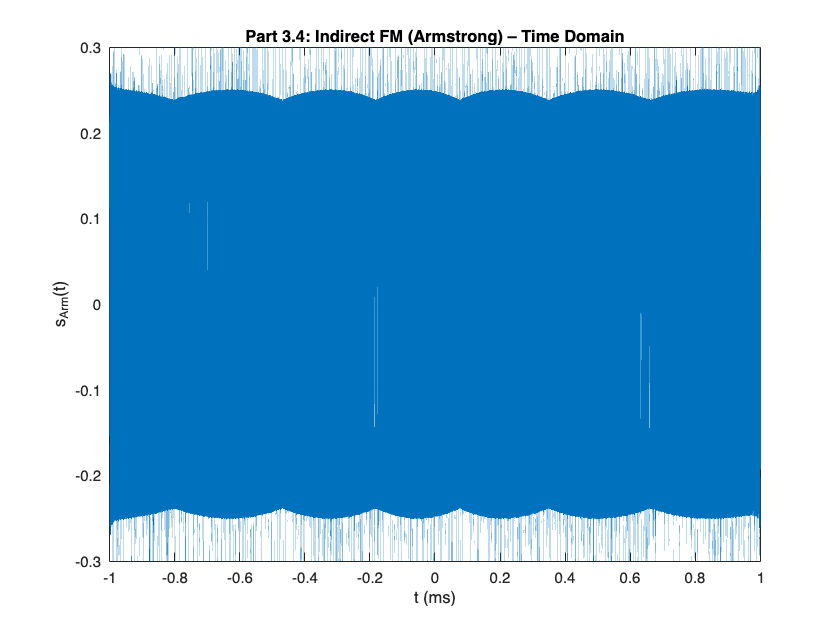

% 3.3) Frequency translation to final carrier (mixing + bandpass select)
% Target carrier similar to Part 2
fc_target = fc;                               % reuse fc=10 MHz from Part 2

% Mix up: choose LO so that (f_car_mult + fLO) = fc_target
fLO = fc_target - f_car_mult;

% Mixer (cosine) creates sum and difference components
xMix = sMULT .* cos(2*pi*fLO*t_rf);           % length = L
L = length(xMix);

Ntmp = 2^nextpow2(L);
XMix = fftshift(fft(xMix, Ntmp))*Ts_rf;
f_tmp = (-Ntmp/2:Ntmp/2-1)*(Fs_rf/Ntmp);

% Keep only a band around fc_target (wide enough for sidebands)
BW_keep = 200e3;                              % +/- 200 kHz around carrier
mask = (abs(f_tmp - fc_target) <= BW_keep);
Xbp = XMix .* mask;

% IFFT gives length Ntmp -> trim back to length L to match t_rf
sArm_full = real(ifft(ifftshift(Xbp))/Ts_rf); % length = Ntmp
sArm = sArm_full(1:L);                        % length = L (matches t_rf)

%% -------------------------------
% 3.4) Time- and frequency-domain plots of indirect FM (Armstrong)
% Time-domain plot (Armstrong)
figure;
plot(t_rf*1e3, sArm, 'LineWidth', 1.0); grid on;
xlabel('t (ms)'); ylabel('s_{Arm}(t)');
title('Part 3.4: Indirect FM (Armstrong) – Time Domain');

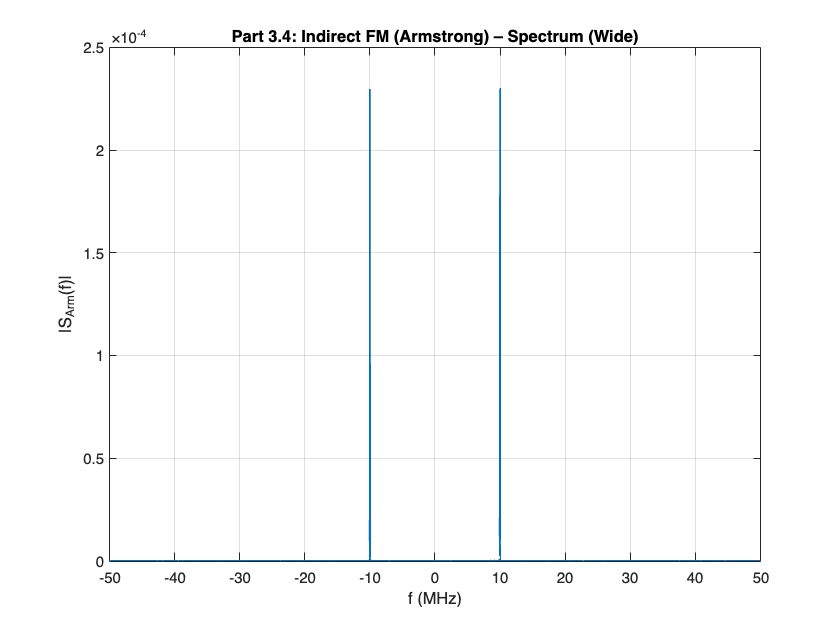


% Magnitude spectrum (linear) with f axis (not f-fc)
Sarm = fftshift(fft(sArm, Ntmp))*Ts_rf;       % reuse N_rf from Part 2 if exists; else N_rf defined here
f_arm = (-Ntmp/2:Ntmp/2-1)*(Fs_rf/Ntmp);

figure;
plot(f_arm/1e6, abs(Sarm), 'LineWidth', 1.2); grid on;
xlabel('f (MHz)'); ylabel('|S_{Arm}(f)|');
title('Part 3.4: Indirect FM (Armstrong) – Spectrum (Wide)');

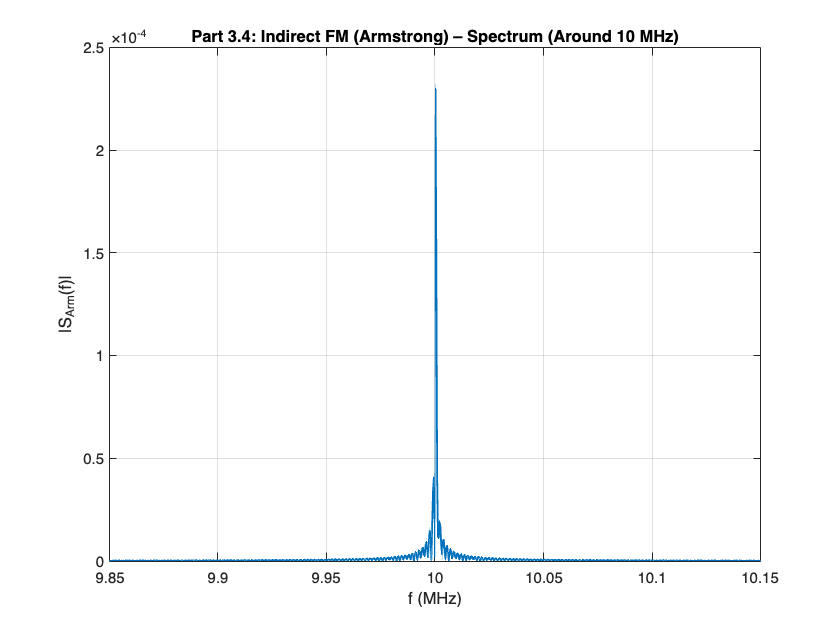


figure;
plot(f_arm/1e6, abs(Sarm), 'LineWidth', 1.2); grid on;
xlabel('f (MHz)'); ylabel('|S_{Arm}(f)|');
title('Part 3.4: Indirect FM (Armstrong) – Spectrum (Around 10 MHz)');
xlim([(fc_target-150e3)/1e6 (fc_target+150e3)/1e6]);

%% 3.5) Compare bandwidth, deviation, spectral shape
% Carson bandwidth estimates (for reporting)
Bc_direct   = 2*(Delta_f + fm_max);          % from Part 2
Bc_armstrong= 2*(fdev_mult + fmA_max);       % after multiplication

fprintf('Part 3.5:\n');

Part 3.5:


fprintf('  Direct FM:     Delta_f=%.0f Hz, fm_max=%.0f Hz, Carson BW≈%.0f Hz\n', Delta_f, fm_max, Bc_direct);

  Direct FM:     Delta_f=20000 Hz, fm_max=2000 Hz, Carson BW≈44000 Hz


fprintf('  Armstrong FM:  Delta_f≈%.1f Hz, fm_max≈%.0f Hz, Carson BW≈%.1f Hz\n', fdev_mult, fmA_max, Bc_armstrong);

  Armstrong FM:  Delta_f≈400.0 Hz, fm_max≈400 Hz, Carson BW≈1600.0 Hz


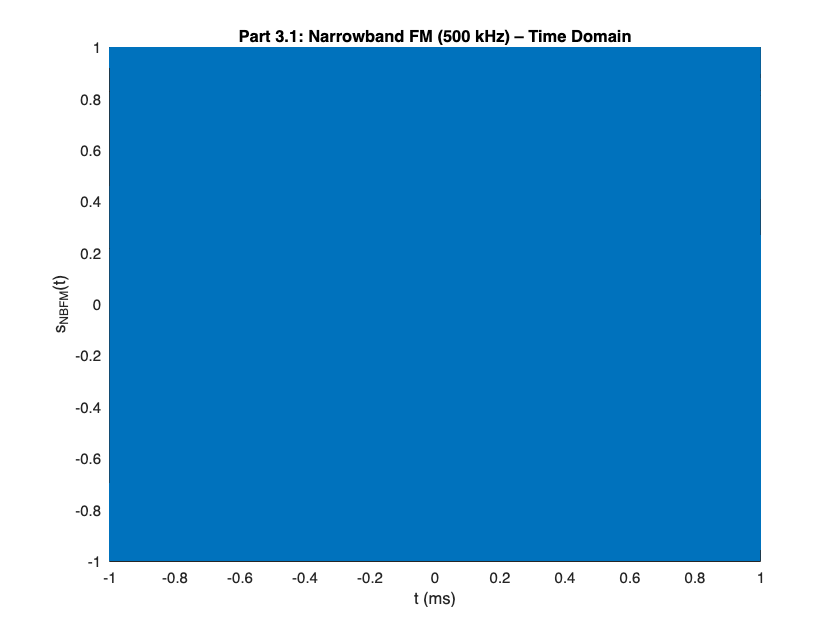

% Spectral-shape comment (for report):
% Direct FM (beta~10) shows wider spread and more significant sidebands.
% Armstrong here starts NBFM and uses modest multiplication -> smaller fdev,
% hence fewer/closer sidebands and narrower spread (in this simulation setting).

%% Additional: Narrowband FM time & spectrum
% Plot time-domain for NBFM around 500 kHz (Narrowband FM)
figure;
plot(t_rf*1e3, sNBFM, 'LineWidth', 1.2); grid on;
xlabel('t (ms)'); ylabel('s_{NBFM}(t)');
title('Part 3.1: Narrowband FM (500 kHz) – Time Domain');

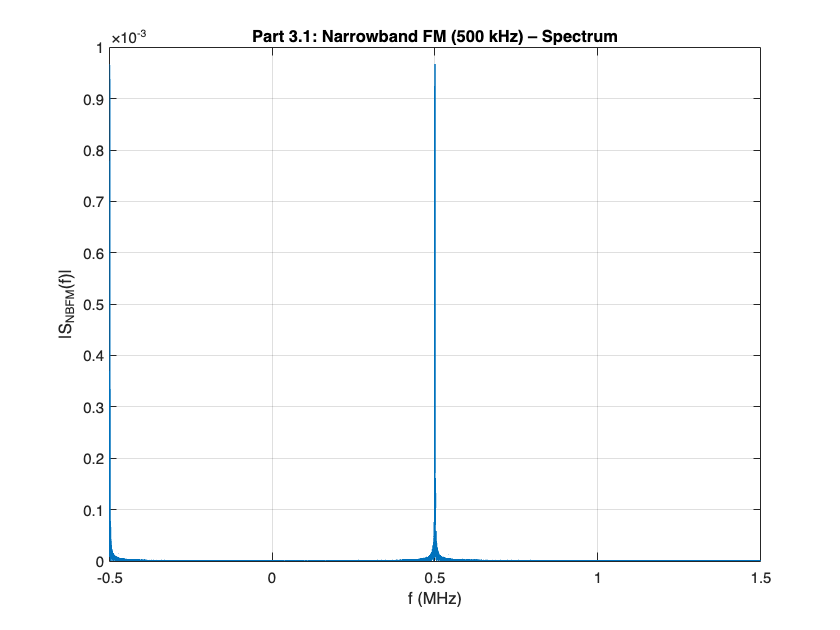

% Spectrum of NBFM at 500 kHz
S_NBFM = fftshift(fft(sNBFM, Ntmp))*Ts_rf;
f_NBFM = (-Ntmp/2:Ntmp/2-1)*(Fs_rf/Ntmp);

figure;
plot(f_NBFM/1e6, abs(S_NBFM), 'LineWidth', 1.2); grid on;
xlabel('f (MHz)'); ylabel('|S_{NBFM}(f)|');
title('Part 3.1: Narrowband FM (500 kHz) – Spectrum');
xlim([fbase/1e6 - 1 fbase/1e6 + 1]);   % Focus around 500 kHz

## PART 4

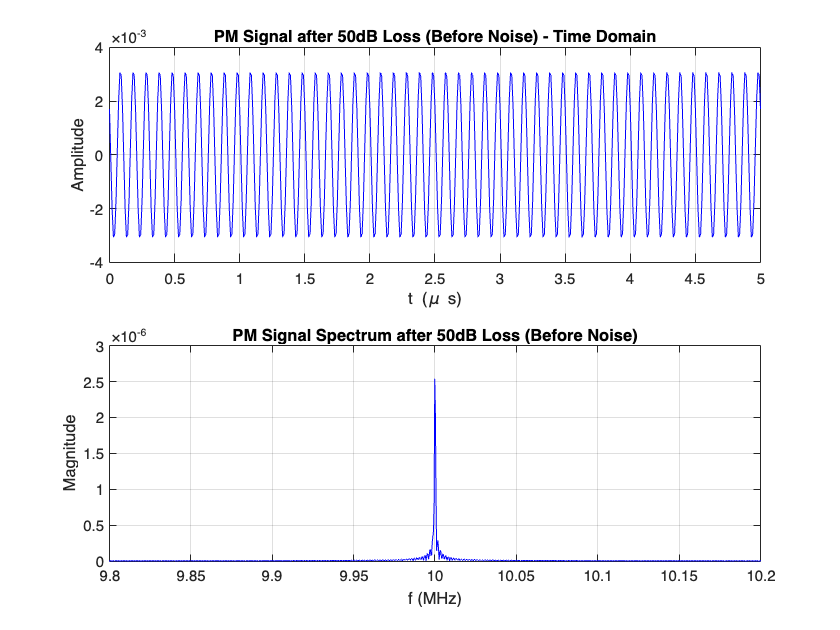

% Part 4: FM and PM through AWGN and SNR Analysis
% This section models channel loss, AWGN, and BPF filtering.

%% 4.1) AWGN Channel Model & Signal Generation
% Channel Parameters
Loss_dB = 50; 
Loss_lin = 10^(-Loss_dB/20);      % Amplitude scaling factor for 50dB loss [cite: 134]
N0_half = 0.5e-12;                % Double-sided PSD (N0/2) [cite: 135]
N0 = 2 * N0_half;                 % Single-sided PSD
Fs = Fs_rf;                       % RF sampling frequency (100 MHz)

% 1. Generate PM Signal (Phase Modulation)
% Assuming kp = 1 for phase deviation based on normalized message
kp = 1.0; 
sPM = cos(2*pi*fc*t_rf + kp*mLPn_rf); 

% 2. Apply Channel Loss to both FM and PM
sFM_loss = sFM * Loss_lin;        % Attenuated FM signal [cite: 134]
sPM_loss = sPM * Loss_lin;        % Attenuated PM signal [cite: 134]

% 3. Generate Additive White Gaussian Noise (AWGN)
% Total noise power = N0 * (Fs/2) across the entire simulation bandwidth
Noise_Power_Full = N0 * (Fs / 2); 
noise = sqrt(Noise_Power_Full) * randn(size(t_rf)); % Zero-mean Gaussian noise [cite: 135]

% 4. Received Signals (Signal + Noise)
rFM = sFM_loss + noise;           % Received FM [cite: 133]
rPM = sPM_loss + noise;           % Received PM [cite: 133]
%% --- Part 4.2: Time- and Frequency-Domain Inspection (Separate Plots) ---
S_PM_clean = fftshift(fft(sPM_loss, N_rf))*Ts_rf;
S_PM_noisy = fftshift(fft(rPM, N_rf))*Ts_rf;
S_FM_clean = fftshift(fft(sFM_loss, N_rf))*Ts_rf;
S_FM_noisy = fftshift(fft(rFM, N_rf))*Ts_rf;



% --- 1. PM Signal: After Loss but BEFORE Noise ---
figure('Name', 'P4.2: PM Signal - After Loss (Clean)');
subplot(2,1,1);
plot(t_rf*1e6, sPM_loss, 'b'); 
xlim([0 5]); grid on; xlabel('t (\mu s)'); ylabel('Amplitude');
title('PM Signal after 50dB Loss (Before Noise) - Time Domain');

subplot(2,1,2);
plot(f_rf/1e6, abs(S_PM_clean), 'b');
xlim([9.8 10.2]); grid on; xlabel('f (MHz)'); ylabel('Magnitude');
title('PM Signal Spectrum after 50dB Loss (Before Noise)');

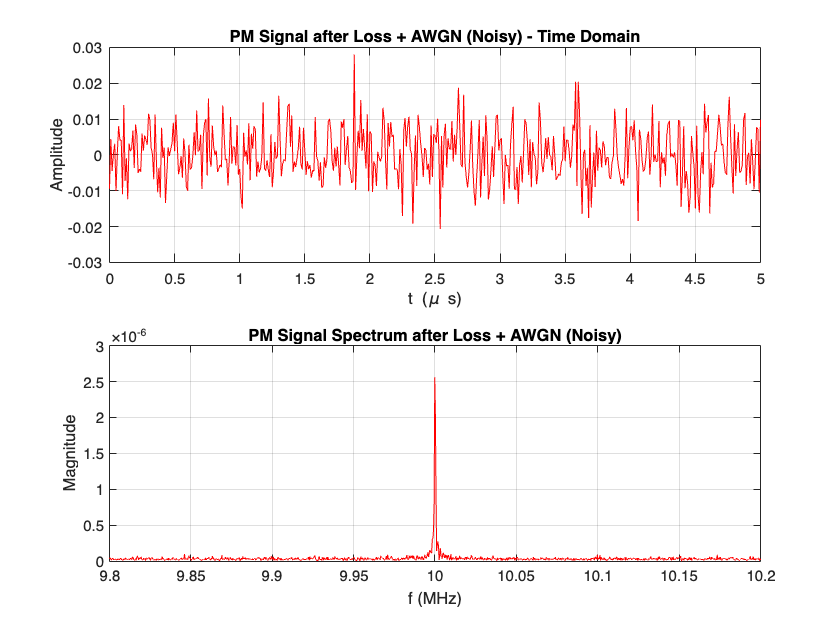


% --- 2. PM Signal: After Loss AND AFTER Noise ---
figure('Name', 'P4.2: PM Signal - After Noise (Noisy)');
subplot(2,1,1);
plot(t_rf*1e6, rPM, 'r'); 
xlim([0 5]); grid on; xlabel('t (\mu s)'); ylabel('Amplitude');
title('PM Signal after Loss + AWGN (Noisy) - Time Domain');

subplot(2,1,2);
plot(f_rf/1e6, abs(S_PM_noisy), 'r');
xlim([9.8 10.2]); grid on; xlabel('f (MHz)'); ylabel('Magnitude');
title('PM Signal Spectrum after Loss + AWGN (Noisy)');

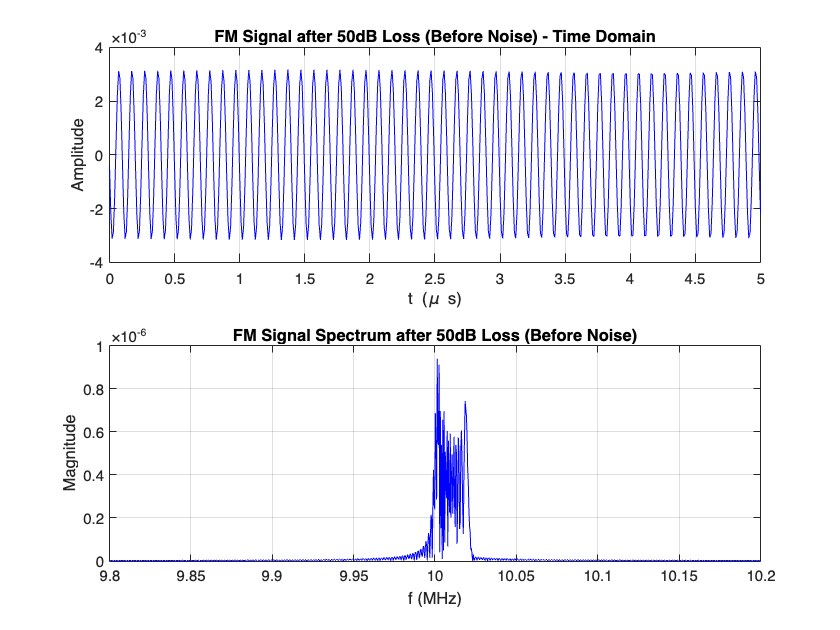


% --- 3. FM Signal: After Loss but BEFORE Noise ---
figure('Name', 'P4.2: FM Signal - After Loss (Clean)');
subplot(2,1,1);
plot(t_rf*1e6, sFM_loss, 'b'); 
xlim([0 5]); grid on; xlabel('t (\mu s)'); ylabel('Amplitude');
title('FM Signal after 50dB Loss (Before Noise) - Time Domain');

subplot(2,1,2);
plot(f_rf/1e6, abs(S_FM_clean), 'b');
xlim([9.8 10.2]); grid on; xlabel('f (MHz)'); ylabel('Magnitude');
title('FM Signal Spectrum after 50dB Loss (Before Noise)');

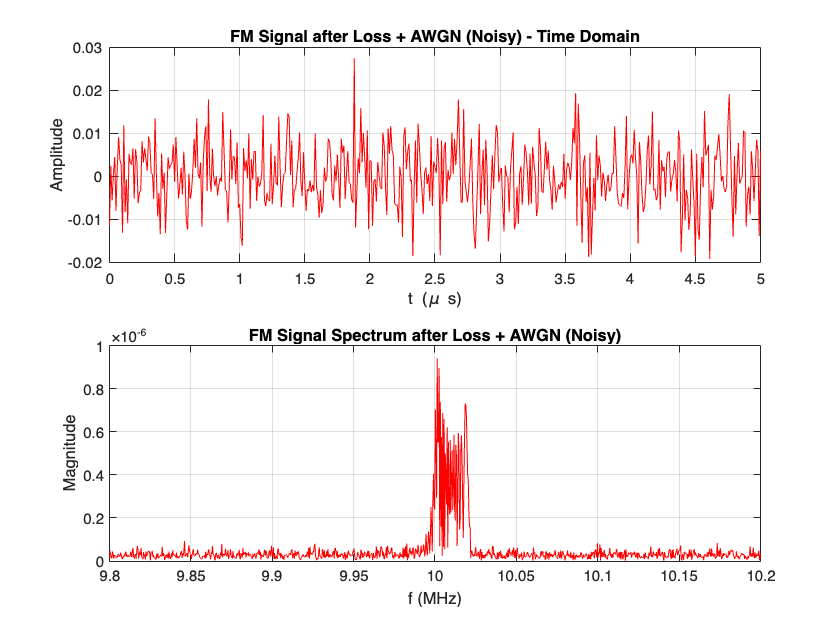


% --- 4. FM Signal: After Loss AND AFTER Noise ---
figure('Name', 'P4.2: FM Signal - After Noise (Noisy)');
subplot(2,1,1);
plot(t_rf*1e6, rFM, 'r'); 
xlim([0 5]); grid on; xlabel('t (\mu s)'); ylabel('Amplitude');
title('FM Signal after Loss + AWGN (Noisy) - Time Domain');

subplot(2,1,2);
plot(f_rf/1e6, abs(S_FM_noisy), 'r');
xlim([9.8 10.2]); grid on; xlabel('f (MHz)'); ylabel('Magnitude');
title('FM Signal Spectrum after Loss + AWGN (Noisy)');

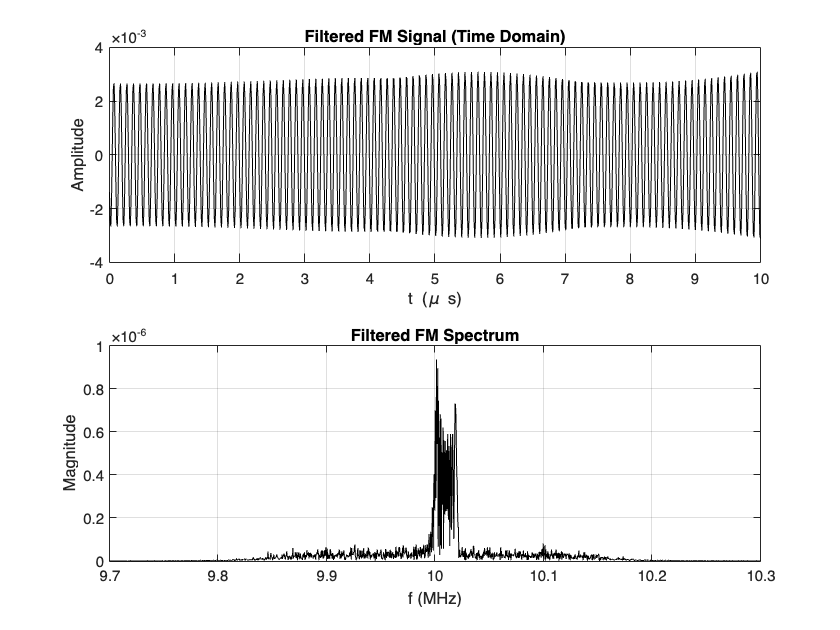

%% 4.3) Noise Reduction using Simple Filtering
% Design a Band-Pass Filter (BPF) [cite: 139, 140]
BW_filter = 150e3; 
[b_bpf, a_bpf] = butter(4, [(fc-BW_filter)/(Fs/2), (fc+BW_filter)/(Fs/2)], 'bandpass');

% Apply Filter [cite: 142]
rFM_filt = filtfilt(b_bpf, a_bpf, rFM); 
rPM_filt = filtfilt(b_bpf, a_bpf, rPM); 

% Calculate FFTs
S_FM_filt = fftshift(fft(rFM_filt, N_rf))*Ts_rf;
S_PM_filt = fftshift(fft(rPM_filt, N_rf))*Ts_rf;

%% Figure 1: FM Results
figure('Name', 'Part 4.3: Filtered FM Signal');
subplot(2,1,1);
plot(t_rf*1e6, rFM_filt, 'k'); 
xlim([0 10]); grid on;
title('Filtered FM Signal (Time Domain)'); xlabel('t (\mu s)'); ylabel('Amplitude');

subplot(2,1,2);
plot(f_rf/1e6, abs(S_FM_filt), 'k'); 
xlim([(fc-300e3)/1e6, (fc+300e3)/1e6]); grid on;
title('Filtered FM Spectrum'); xlabel('f (MHz)'); ylabel('Magnitude');

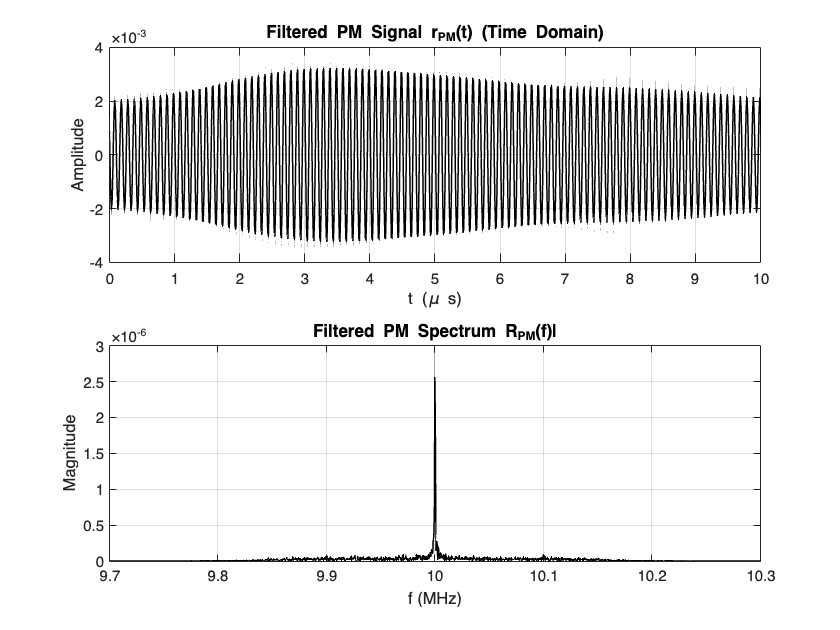


%% Figure 2: PM Results (Added separate figure command)
figure('Name', 'Part 4.3: Filtered PM Signal');
subplot(2,1,1);
plot(t_rf*1e6, rPM_filt, 'k', 'LineWidth', 1); 
xlim([0 10]); grid on;
title('Filtered PM Signal {r}_{PM}(t) (Time Domain)'); 
xlabel('t (\mu s)'); ylabel('Amplitude');

subplot(2,1,2);
plot(f_rf/1e6, abs(S_PM_filt), 'k', 'LineWidth', 1); 
xlim([(fc-300e3)/1e6, (fc+300e3)/1e6]); grid on;
title('Filtered PM Spectrum {R}_{PM}(f)|'); 
xlabel('f (MHz)'); ylabel('Magnitude');


%% 4.4) Output SNR Comparison
% 1. SNR at Transmitter (Before channel loss) [cite: 147]
P_sig_FM_tx = mean(sFM.^2); 
P_sig_PM_tx = mean(sPM.^2); 
SNR_FM_tx = 10 * log10(P_sig_FM_tx / Noise_Power_Full);
SNR_PM_tx = 10 * log10(P_sig_PM_tx / Noise_Power_Full);

% 2. SNR at Receiver (After loss, before BPF) [cite: 148, 153]
P_sig_FM_rx = mean(sFM_loss.^2);
P_sig_PM_rx = mean(sPM_loss.^2);
SNR_FM_rx = 10 * log10(P_sig_FM_rx / Noise_Power_Full);
SNR_PM_rx = 10 * log10(P_sig_PM_rx / Noise_Power_Full);

% 3. SNR after BPF (Post-filtering) [cite: 148]
% Noise power is calculated as the variance of the residual error
P_noise_bpf_fm = mean((rFM_filt - sFM_loss).^2);
P_noise_bpf_pm = mean((rPM_filt - sPM_loss).^2);
SNR_FM_bpf = 10 * log10(P_sig_FM_rx / P_noise_bpf_fm);
SNR_PM_bpf = 10 * log10(P_sig_PM_rx / P_noise_bpf_pm);

% Display results 
fprintf('[P4.4] SNR_tx  (pre-channel)      FM=%.4f dB, PM=%.4f dB\n', SNR_FM_tx,  SNR_PM_tx);

[P4.4] SNR_tx  (pre-channel)      FM=40.0000 dB, PM=40.0000 dB


fprintf('[P4.4] SNR_rx  (after loss, pre-BPF) FM=%.4f dB, PM=%.4f dB\n', SNR_FM_rx,  SNR_PM_rx);

[P4.4] SNR_rx  (after loss, pre-BPF) FM=-10.0000 dB, PM=-10.0000 dB


fprintf('[P4.4] SNR_bpf or SNR_Out (post-BPF, pre-demod) FM=%.4f dB, PM=%.4f dB\n', SNR_FM_bpf, SNR_PM_bpf);

[P4.4] SNR_bpf or SNR_Out (post-BPF, pre-demod) FM=12.3879 dB, PM=12.3916 dB


## PART 5

% Part 5: FM Demodulation and Error Comparison (Final Optimized)
% This section recovers the message using two methods and compares
% them against the original transmitted message.

% --- Initial Setup & Decimation Factor ---
% Calculate decimation factor to downsample from RF to Baseband
D = round(Fs_rf / Fs_bb); 

% Design Post-Detection Low Pass Filter (LPF)
% The cutoff is set slightly above the effective bandwidth (Beff)
Fc_post = min(1.2 * Beff_bb, 0.45 * Fs_bb); 
[b_post, a_post] = butter(4, Fc_post / (Fs_bb/2));

% Create the Baseband Reference Signal
% We resample the transmitted normalized message (mLPn_rf) to baseband
m_ref_bb = resample(mLPn_rf(:), 1, D); 

% Define Baseband Time Vector for Plotting
t_bb_hat = (0:numel(m_ref_bb)-1).' / Fs_bb + t_rf(1);

%% 5.0) Pre-processing: Limiter / AGC
% Critical Step: Normalize signal amplitude before demodulation.
% The 50dB channel loss makes the signal amplitude very small (~1e-3).
% Without this, demodulators (especially differentiation) may suffer 
% from numerical precision errors.
if max(abs(rFM_filt)) > 1e-15
    rFM_norm = rFM_filt / max(abs(rFM_filt));
else
    rFM_norm = rFM_filt;
end

%% 5.1) Method 1: FM Demodulation using fmdemod
% 1. Demodulate at RF rate
m_hat1_rf = fmdemod(rFM_norm, fc, Fs_rf, Delta_f); 

% 2. Downsample to Baseband
m_hat1_bb = resample(m_hat1_rf(:), 1, D);

% 3. Apply Post-Detection LPF to remove high-frequency noise
m_hat1_bb = filtfilt(b_post, a_post, m_hat1_bb);

%% 5.2) Method 2: FM Demodulation using Discriminator
% Concept: Differentiator -> Envelope Detector -> LPF

% A) Extract Instantaneous Phase using Hilbert Transform
z = hilbert(rFM_norm(:));    
phi = unwrap(angle(z));

% B) Differentiate Phase to get Instantaneous Frequency
% d(phi)/dt = 2*pi*f_inst  =>  f_inst = (1/2pi) * diff(phi)/Ts
dphi = [0; diff(phi)]; 
instfreq = dphi * (Fs_rf / (2*pi)); % Frequency in Hz

% C) Remove Carrier and Normalize by Frequency Deviation
m_hat2_rf = (instfreq - fc) / Delta_f;

% D) Downsample to Baseband and Filter
m_hat2_bb = resample(m_hat2_rf(:), 1, D);
m_hat2_bb = filtfilt(b_post, a_post, m_hat2_bb);

%% 5.3) Synchronization and NMSE Calculation
% To compute Error correctly, we must align Time and Amplitude.

% --- A. Time Delay Alignment (Cross-Correlation) ---
L_corr = min(2000, length(m_ref_bb)-1); % Max lag to check

% Align Method 1
[cc1, lags] = xcorr(m_ref_bb, m_hat1_bb, L_corr);
[~, I1] = max(abs(cc1));
lag1 = lags(I1);

if lag1 > 0
    % Reference is ahead, delay hat1
    m_hat1_sync = [m_hat1_bb(lag1+1:end); zeros(lag1,1)];
else
    % Reference is behind, pad hat1
    m_hat1_sync = [zeros(-lag1,1); m_hat1_bb(1:end+lag1)];
end

% Align Method 2
[cc2, ~] = xcorr(m_ref_bb, m_hat2_bb, L_corr);
[~, I2] = max(abs(cc2));
lag2 = lags(I2);

if lag2 > 0
    m_hat2_sync = [m_hat2_bb(lag2+1:end); zeros(lag2,1)];
else
    m_hat2_sync = [zeros(-lag2,1); m_hat2_bb(1:end+lag2)];
end

% --- B. Amplitude Scaling (Gain Correction) ---
% LPFs and channel effects might introduce slight gain errors.
% We calculate scaling factor k to minimize squared error: k = (ref . hat) / (hat . hat)

% Truncate vectors to common length for calculation
L_common = min([numel(m_ref_bb), numel(m_hat1_sync), numel(m_hat2_sync)]);
ref_cut  = m_ref_bb(1:L_common);
hat1_cut = m_hat1_sync(1:L_common);
hat2_cut = m_hat2_sync(1:L_common);

% Calculate scalar gains
k1 = sum(ref_cut .* hat1_cut) / (sum(hat1_cut.^2) + eps);
m_hat1_final = hat1_cut * k1;

k2 = sum(ref_cut .* hat2_cut) / (sum(hat2_cut.^2) + eps);
m_hat2_final = hat2_cut * k2;

% --- C. Normalized Mean-Square Error (NMSE) ---
% We ignore the first and last 10% of samples to avoid filter transient effects
cut_len = floor(0.1 * L_common);
eval_idx = (cut_len : L_common - cut_len);

ref_eval  = ref_cut(eval_idx);
hat1_eval = m_hat1_final(eval_idx);
hat2_eval = m_hat2_final(eval_idx);

Enorm1 = sum((ref_eval - hat1_eval).^2) / sum(ref_eval.^2);
Enorm2 = sum((ref_eval - hat2_eval).^2) / sum(ref_eval.^2);

% Print Results
fprintf('\n[Part 5 Results]\n');


[Part 5 Results]


fprintf('  NMSE Method 1 (fmdemod)       = %.5e\n', Enorm1);

  NMSE Method 1 (fmdemod)       = 1.35191e-02


fprintf('  NMSE Method 2 (Discriminator) = %.5e\n', Enorm2);

  NMSE Method 2 (Discriminator) = 1.25296e-02


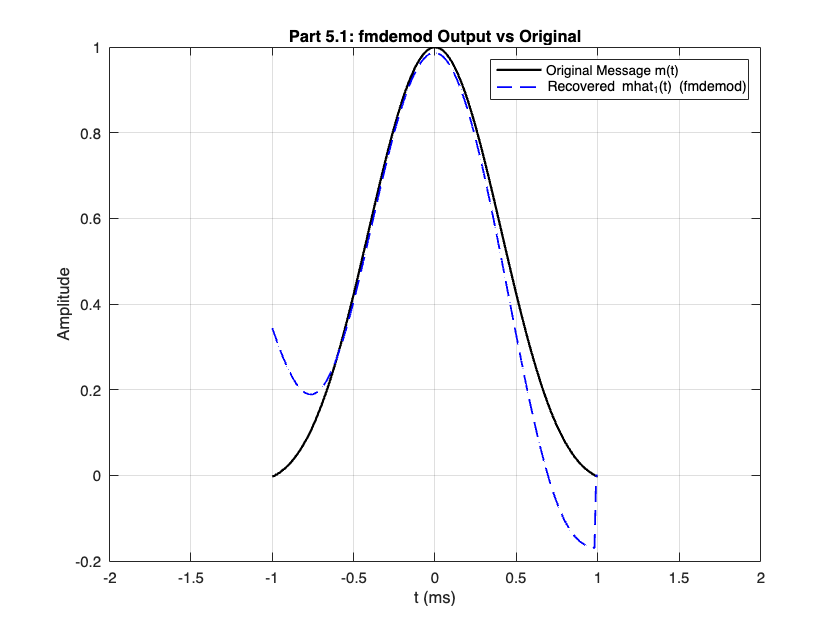

%% --- D. Plotting (High Resolution FFT) ---

t_plot = t_bb_hat(1:L_common) * 1e3; 

N_fft = 2^nextpow2(L_common * 32); 
f_axis = (-N_fft/2 : N_fft/2 - 1) * (Fs_bb / N_fft);

Ref_spec  = fftshift(fft(ref_cut, N_fft));
Hat1_spec = fftshift(fft(m_hat1_final, N_fft));
Hat2_spec = fftshift(fft(m_hat2_final, N_fft));

% --- Figure 5.1: Method 1 (fmdemod) vs Original ---
figure('Name', 'Part 5.1: fmdemod Recovery');
plot(t_plot, ref_cut, 'k', 'LineWidth', 1.5); hold on;
plot(t_plot, m_hat1_final, 'b--', 'LineWidth', 1.2);
grid on; xlabel('t (ms)'); ylabel('Amplitude');
legend('Original Message m(t)', 'Recovered {mhat}_1(t) (fmdemod)');
title('Part 5.1: fmdemod Output vs Original');
xlim([-2 2]); 

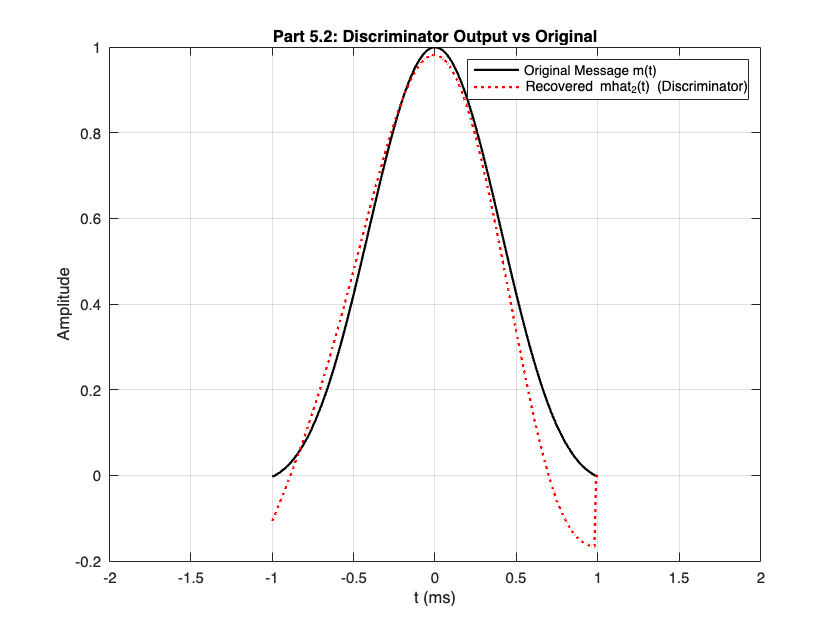


% --- Figure 5.2: Method 2 (Discriminator) vs Original ---
figure('Name', 'Part 5.2: Discriminator Recovery');
plot(t_plot, ref_cut, 'k', 'LineWidth', 1.5); hold on;
plot(t_plot, m_hat2_final, 'r:', 'LineWidth', 1.5);
grid on; xlabel('t (ms)'); ylabel('Amplitude');
legend('Original Message m(t)', 'Recovered {mhat}_2(t) (Discriminator)');
title('Part 5.2: Discriminator Output vs Original');
xlim([-2 2]);

% --- Figure 5.3: Combined Comparison (High Res Spectrum) ---

% Calculate the energy of the original reference signal (Denominator)
% Formula: Integral(m(t)^2) -> Sum(m(t)^2) in discrete domain
Energy_m = sum(ref_cut.^2);

% Method 1: fmdemod 
% Calculate the squared error for the 'fmdemod' output
Error_1 = sum((ref_cut - m_hat1_final).^2);

% Calculate Normalized MSE for Method 1
Enorm_1 = Error_1 / Energy_m;

% --- Method 2: Discriminator ---
% Calculate the squared error for the 'Discriminator' output
Error_2 = sum((ref_cut - m_hat2_final).^2);

% Calculate Normalized MSE for Method 2
Enorm_2 = Error_2 / Energy_m;

% --- Display Results ---
fprintf('\n--- Part 5.3: Normalized Error Comparison ---\n');


--- Part 5.3: Normalized Error Comparison ---


fprintf('Normalized MSE for fmdemod (Enorm_1):       %.5e\n', Enorm_1);

Normalized MSE for fmdemod (Enorm_1):       3.90935e-02


fprintf('Normalized MSE for Discriminator (Enorm_2): %.5e\n', Enorm_2);

Normalized MSE for Discriminator (Enorm_2): 2.17499e-02


% Automated comparison
if Enorm_1 < Enorm_2
    fprintf('Conclusion: "fmdemod" performed better (lower error).\n');
else
    fprintf('Conclusion: "Discriminator" performed better (lower error).\n');
end

Conclusion: "Discriminator" performed better (lower error).


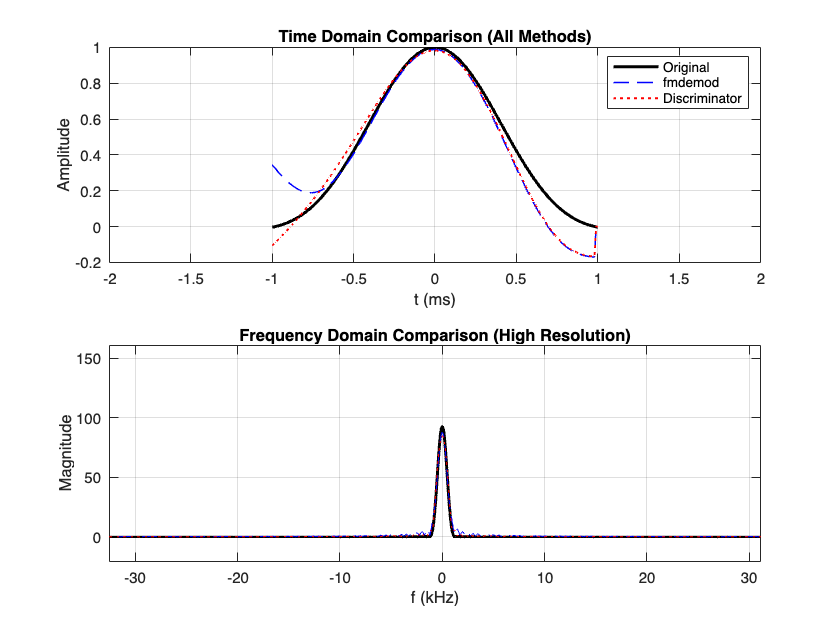


figure('Name', 'Part 5.3: Final Comparison');
subplot(2,1,1);
plot(t_plot, ref_cut, 'k', 'LineWidth', 2); hold on;
plot(t_plot, m_hat1_final, 'b--', 'LineWidth', 1);
plot(t_plot, m_hat2_final, 'r:', 'LineWidth', 1.2);
grid on; xlabel('t (ms)'); ylabel('Amplitude');
legend('Original', 'fmdemod', 'Discriminator');
title('Time Domain Comparison (All Methods)');
xlim([-2 2]);

subplot(2,1,2);
plot(f_axis/1e3, abs(Ref_spec), 'k', 'LineWidth', 2); hold on;
plot(f_axis/1e3, abs(Hat1_spec), 'b--');
plot(f_axis/1e3, abs(Hat2_spec), 'r:');
grid on; xlabel('f (kHz)'); ylabel('Magnitude');
title('Frequency Domain Comparison (High Resolution)');
xlim([-5 5]);

## PART 6

% Part 6: Audio FDM System (Full Visualization)
% Covers sections 6.1 to 6.8 with ALL requested plots

%% SECTION A: Intelligent Audio Loader 
% (Loads existing .mat files or converts .m4a/.wav automatically)
audio_files = {'voice1.m4a', 'voice2.m4a', 'voice3.m4a'}; 
mat_files   = {'voice1.mat', 'voice2.mat', 'voice3.mat'};
var_names   = {'voice1', 'voice2', 'voice3'};

raw_signals = cell(1, 3);
Fs_input    = zeros(1, 3);

fprintf('--- Section A: Checking Audio Files ---\n');

--- Section A: Checking Audio Files ---


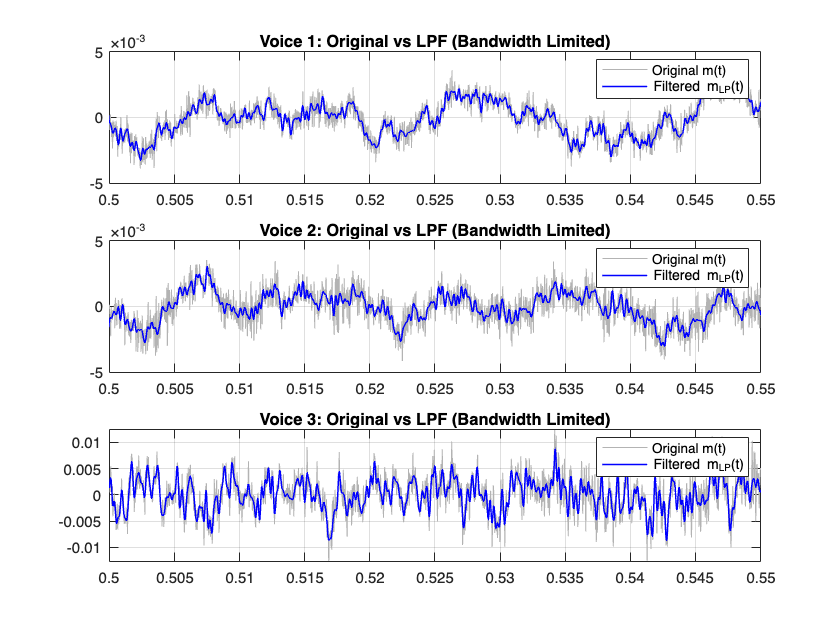

for i = 1:3
    if isfile(mat_files{i})
        data = load(mat_files{i});
        if isfield(data, var_names{i}), raw_signals{i} = data.(var_names{i}); Fs_input(i) = data.Fs_audio; end
    elseif isfile(audio_files{i})
        try
            [y, fs] = audioread(audio_files{i});
            if size(y, 2) > 1, y = mean(y, 2); end % Mono
            S.(var_names{i}) = y; S.Fs_audio = fs;
            save(mat_files{i}, '-struct', 'S');
            raw_signals{i} = y; Fs_input(i) = fs;
            fprintf('Converted "%s" to .mat\n', audio_files{i});
        catch, warning('Error reading %s', audio_files{i}); end
    end
end

%% SECTION B: Pre-processing (6.2, 6.3)
Fs_process = 44100; T_syn = 3;
m_orig = cell(1, 3);

% Prepare Signals
for i = 1:3
    if isempty(raw_signals{i})
        t_syn = 0:1/Fs_process:T_syn-1/Fs_process;
        if i==1, sig = sin(2*pi*440*t_syn'); elseif i==2, sig = chirp(t_syn', 100, T_syn, 2000); else, sig = sawtooth(2*pi*50*t_syn'); end
    else
        sig = raw_signals{i};
        if Fs_input(i) ~= Fs_process, sig = resample(sig, Fs_process, Fs_input(i)); end
    end
    sig = sig / (max(abs(sig)) + eps); % Normalize
    m_orig{i} = sig;
end

% Equalize lengths
L_min = min([length(m_orig{1}), length(m_orig{2}), length(m_orig{3})]);
m1 = m_orig{1}(1:L_min); m2 = m_orig{2}(1:L_min); m3 = m_orig{3}(1:L_min);
Fs_in = Fs_process;

% 6.3 Bandwidth Limiting (LPF) & PLOTTING 
BW_limit = 4000; % Limit to 4kHz
[b_lp, a_lp] = butter(10, BW_limit/(Fs_in/2));
m1_lp = filtfilt(b_lp, a_lp, m1);
m2_lp = filtfilt(b_lp, a_lp, m2);
m3_lp = filtfilt(b_lp, a_lp, m3);

% [PLOT 6.3] Original vs LPF
figure('Name', 'Part 6.3: Bandwidth Limiting (Original vs LPF)');
t_audio = (0:L_min-1)/Fs_in;
for i = 1:3
    subplot(3,1,i);
    if i==1, sig_orig=m1; sig_lp=m1_lp; elseif i==2, sig_orig=m2; sig_lp=m2_lp; else, sig_orig=m3; sig_lp=m3_lp; end
    
    plot(t_audio, sig_orig, 'Color', [0.7 0.7 0.7]); hold on; % Gray for original
    plot(t_audio, sig_lp, 'b', 'LineWidth', 1);
    title(sprintf('Voice %d: Original vs LPF (Bandwidth Limited)', i));
    legend('Original m(t)', 'Filtered m_{LP}(t)');
    xlim([0.5 0.55]); % Zoom to see filtering effect
    grid on;
end

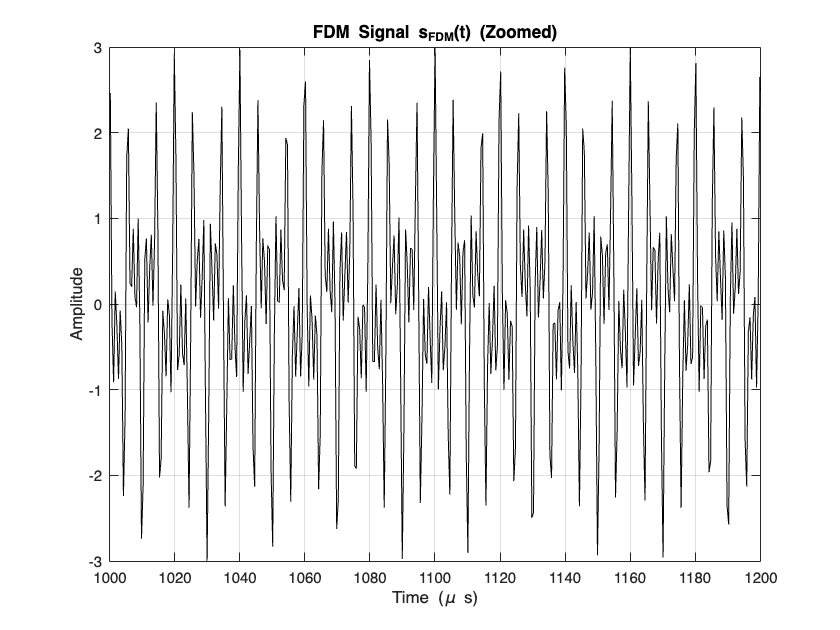


%% --- SECTION C: FDM Construction (6.4, 6.5) ---
% Upsample to RF
Fs_fdm = 2e6; D_up = round(Fs_fdm / Fs_in); Fs_fdm = D_up * Fs_in;
m1_rf = resample(m1_lp, D_up, 1);
m2_rf = resample(m2_lp, D_up, 1);
m3_rf = resample(m3_lp, D_up, 1);

fc = [150e3, 350e3, 550e3];
Delta_f = 15e3;

s1 = fmmod(m1_rf, fc(1), Fs_fdm, Delta_f);
s2 = fmmod(m2_rf, fc(2), Fs_fdm, Delta_f);
s3 = fmmod(m3_rf, fc(3), Fs_fdm, Delta_f);
s_FDM = s1 + s2 + s3;

% [PLOT 6.4] sFDM(t)
figure('Name', 'Part 6.4: FDM Signal s_FDM(t)');
t_rf = (0:length(s_FDM)-1)/Fs_fdm;
plot(t_rf*1e6, s_FDM, 'k');
title('FDM Signal s_{FDM}(t) (Zoomed)');
xlabel('Time (\mu s)'); ylabel('Amplitude');
xlim([1000 1200]); % Zoom in to see carrier oscillations
grid on;

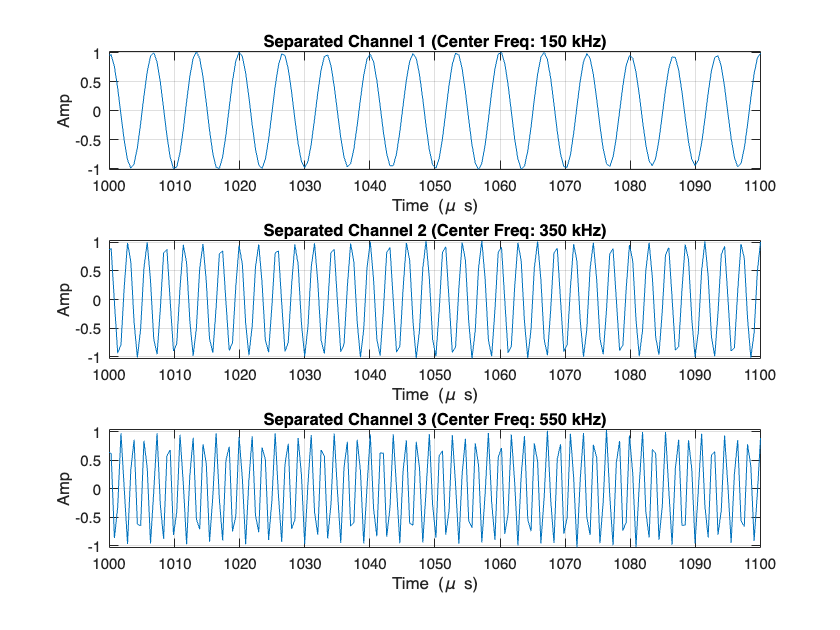


% --- 6.5 AWGN Channel ---
SNR_dB = 20;
r_FDM = awgn(s_FDM, SNR_dB, 'measured');

%% --- SECTION D: Separation (6.6) & PLOTTING ---
BW_pass = 50e3;
r_sep_all = cell(1,3);

% [PLOT 6.6] Separated Signals (s_hat / r_sep)
figure('Name', 'Part 6.6: Separated FM Channels (s_{hat})');

for i = 1:3
    % Filtering
    [b_bp, a_bp] = butter(4, [(fc(i)-BW_pass/2) (fc(i)+BW_pass/2)]/(Fs_fdm/2));
    r_sep = filtfilt(b_bp, a_bp, r_FDM);
    r_sep_all{i} = r_sep;
    
    % Plotting Time Domain of separated RF signal
    subplot(3,1,i);
    plot(t_rf*1e6, r_sep);
    title(sprintf('Separated Channel %d (Center Freq: %.0f kHz)', i, fc(i)/1e3));
    xlabel('Time (\mu s)'); ylabel('Amp');
    xlim([1000 1100]); % Zoom to see sine waves
    grid on;
end


%% --- SECTION E: Demodulation (6.7) & Comparison (6.8) ---
m_hat = cell(1, 3);
fprintf('\n--- 6.8 Normalized Error Metrics and Comparison ---\n');


--- 6.8 Normalized Error Metrics and Comparison ---


fprintf('| Voice |   NMSE    |\n|-------|-----------|\n');

| Voice |   NMSE    |
|-------|-----------|



ref_sigs_plot = cell(1,3);
rec_sigs_plot = cell(1,3);

for i = 1:3
    % Demodulation
    m_demod_rf = fmdemod(r_sep_all{i}, fc(i), Fs_fdm, Delta_f);
    m_demod_bb = resample(m_demod_rf, 1, D_up);
    m_rec = filtfilt(b_lp, a_lp, m_demod_bb); % Final LPF
    
    % Synchronization & Metrics
    if i==1, ref=m1_lp; elseif i==2, ref=m2_lp; else, ref=m3_lp; end
    rec = m_rec;
    L_c = min(length(ref), length(rec));
    ref = ref(1:L_c); rec = rec(1:L_c);
    
    % Time Sync
    [xc, lags] = xcorr(ref, rec);
    [~, I] = max(abs(xc));
    lag = lags(I);
    if lag > 0, rec = [rec(lag+1:end); zeros(lag,1)];
    else, rec = [zeros(-lag,1); rec(1:end+lag)];
    end
    
    % Gain Sync
    k = sum(ref.*rec)/sum(rec.^2);
    rec = rec * k;
    
    % Trim Transient (10%)
    trim = floor(0.1*L_c);
    ref = ref(trim:end-trim);
    rec = rec(trim:end-trim);
    
    % Store for Plotting
    ref_sigs_plot{i} = ref;
    rec_sigs_plot{i} = rec;
    
    % [PRINT 6.8] Normalized Error
    Enorm = sum((ref - rec).^2) / sum(ref.^2);
    fprintf('|   %d   | %.5e |\n', i, Enorm);
end

|   1   | 3.41404e-04 |
|   2   | 5.20847e-04 |
|   3   | 2.58819e-04 |


fprintf('|-------|-----------|\n');

|-------|-----------|


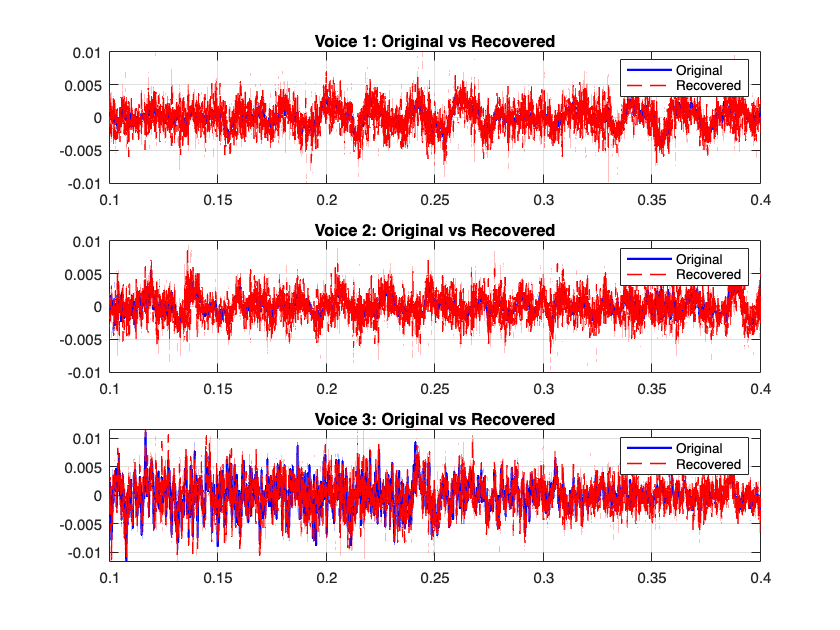


% [PLOT 6.7] Demodulated Voices
figure('Name', 'Part 6.7: Recovered Voices (m_hat)');
t_axis = (0:length(ref_sigs_plot{1})-1)/Fs_in;
for i = 1:3
    subplot(3,1,i);
    plot(t_axis, ref_sigs_plot{i}, 'b', 'LineWidth', 1.5); hold on;
    plot(t_axis, rec_sigs_plot{i}, 'r--', 'LineWidth', 1);
    title(sprintf('Voice %d: Original vs Recovered', i));
    legend('Original', 'Recovered'); grid on;
    xlim([0.1 0.4]); % Zoom on a clear segment
end